# Sinusoid Response

## Setup

clear all;
close all;
clc;

## Scelta della FDT

sys = zpk([0, 0], [-1, -1, -10, -10], 100)

sys =
 
      100 s^2
  ----------------
  (s+1)^2 (s+10)^2
 
Continuous-time zero/pole/gain model.



sys = tf(sys);

## Scelta della pulsazione della sinusoide e periodo associato

w = 1

w = 1

f = w / 2 / pi

f = 0.1592

T = 1 / f

T = 6.2832

## Calcolo della risposta

### Funzioni custom

#### Variabili simboliche

syms u(t) U(s)
syms y(t) Y(s)

#### Ingresso

u(t) = sin(w*t)

$$u(t) = \sin\left(t\right)$$

U(s) = laplace(u)

$$U(s) = \frac{1}{s^{2}+1}$$

#### Matrici dinamiche

[A,B,C,D] = tf2ss(sys.Numerator{1}, sys.Denominator{1})

A =    -22  -141  -220  -100
     1     0     0     0
     0     1     0     0
     0     0     1     0


B =      1
     0
     0
     0


C =      0   100     0     0


D = 0

eig(A)

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


#### Funzione di trasferimento

G(s) = transfer_function(A,B,C,D)

$$G(s) = \frac{100\,s^{2}}{s^{4}+22\,s^{3}+141\,s^{2}+220\,s+100}$$

#### Uscita

Y(s) = G(s) * U(s)

$$Y(s) = \frac{100\,s^{2}}{\left(s^{2}+1\right)\,\left(s^{4}+22\,s^{3}+141\,s^{2}+220\,s+100\right)}$$

y(t) = simplify(ilaplace(Y(s)));
disp(vpa(y, 2))

$$0.27\,{\mathrm{e}}^{-10.0\,t}-0.75\,{\mathrm{e}}^{-1.0\,t}+0.49\,\cos\left(t\right)+0.098\,\sin\left(t\right)+0.62\,t\,{\mathrm{e}}^{-1.0\,t}+1.2\,t\,{\mathrm{e}}^{-10.0\,t}$$

#### Grafico

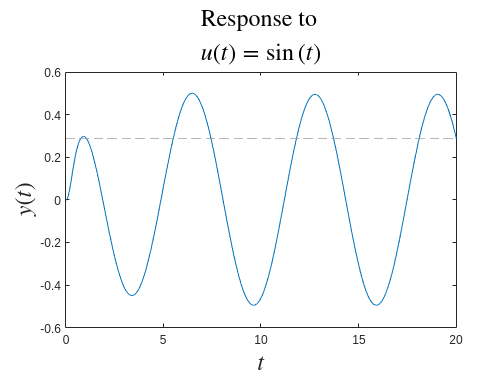

% Creare una nuova figura
figure('Name','Evoluzione forzata')

% Tempo limite per il grafico
TF = 20;
% Numero di campioni da graficare
NS = 10000;
% Intervallo di campionamento
TS = TF / NS;
% Definizione dell'asse temporale
tt = linspace(0, TF, NS);

% Grafico
plot(tt, y(tt));
xlim([tt(1) tt(end)])
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(y(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title(['Response to $$u(t)=' latex(u) '$$'],...
    'Interpreter','latex', 'FontSize',20)

### Funzioni built-int di MATLAB

#### Definizione dell'ingresso

[u, time] = gensig("sine", T, TF, TS);

#### Definizione dell'uscita

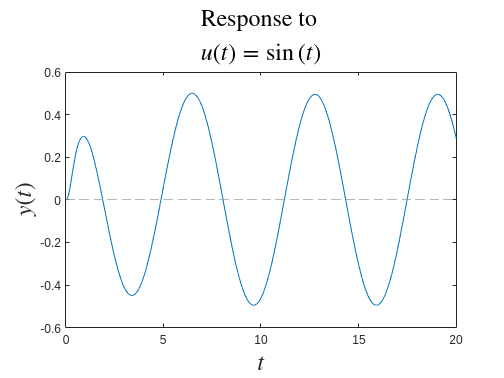

figure;
[y, time] = lsim(sys, u, time);
plot(time, y');
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(y(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title(['Response to $$u(t)=' latex(sin(w*t)) '$$'],...
    'Interpreter','latex', 'FontSize',20)

## Modifica del parametro w

w = 100

w = 100

f = w / 2 / pi

f = 15.9155

T = 1 / f

T = 0.0628

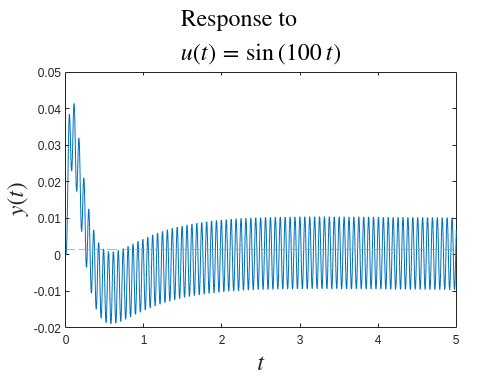

TF = 5;
TS = TF / NS;
[u, time] = gensig("sine", T, TF, TS);
figure;
[y, time] = lsim(sys, u, time);
plot(time, y');
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$y(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(double(y(tt(end))), '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title(['Response to $$u(t)=' latex(sin(w*t)) '$$'],...
    'Interpreter','latex', 'FontSize',20)